## Dimensionering af bagakslen

Vi har regnet drivkraften $F_D$ og normalkraften på bagakslen $N_B$ i filen bil_ligevaegt.mlx og kædekraften $F_K$ samt lejereaktionerne $R_{1y}, R_{2y}, R_{1z}, R_{2z}$ på akslen i aksel_ligevaegt.mlx.

**Maksimalt bøjningsmoment**

Bøjningsmomentet $\sigma_x$ er


$$\sigma_x = - \frac{M_zy}{I_z} + \frac{M_y y}{I_y}$$


For en cirkulær stang er inertimomentet $I = \frac{\pi d^4}{64}$ og det yderste punkt er ved $y = d/2$. Derfor er det maksimale bøjningsmoment:


$$\sigma_{x,max} = \frac{32}{\pi d^3} \sqrt{M_y^2 + M_z^2}$$


**Maksimal forskydningsspænding**

Torsionsformlen er


$$\tau_v = \frac{T_v r}{J}$$


For en massiv rund aksel er


$$J = \frac{\pi D^4}{32}, \quad r_{max} = \frac{D}{2}$$


Derfor


$$\tau_{v,max} = \frac{16T}{\pi D^3}$$


**Von Mises**

Von Mises spændingen $\sigma_{vM}$ er:


$$\sigma_{vM} = \sqrt{\sigma^2 + 3\tau^2}$$


Den maksimale von Mises spænding bliver derfor


$$\sigma_{vM} = \sqrt{\left( \frac{32 M}{\pi D^3} \right)^2 + 3 \left( \frac{16T}{\pi D^3} \right)^2}$$


**Sikkerhedsfaktor mod plasticering**

Vi dimensionerer med en sikkerhedsfaktor mod plasticering på $n = 2$ efter


$$\sigma_{vM} \leq \frac{\sigma_y}{n}$$


**Notches**

Ved en notch har vi


$$\sigma_{lokal} = K_{t,b} \sigma_{nom}$$



$$\tau_{lokal} = K_{t,v} \tau_{nom}$$



$$\sigma_{VM,lokal} = \sqrt{\sigma_{lokal}^2 + \tau_{lokal}^2} = \sqrt{(K_{t,b} \sigma_{nom})^2 + 3 (K_{t,v} \tau_{nom})^2}$$


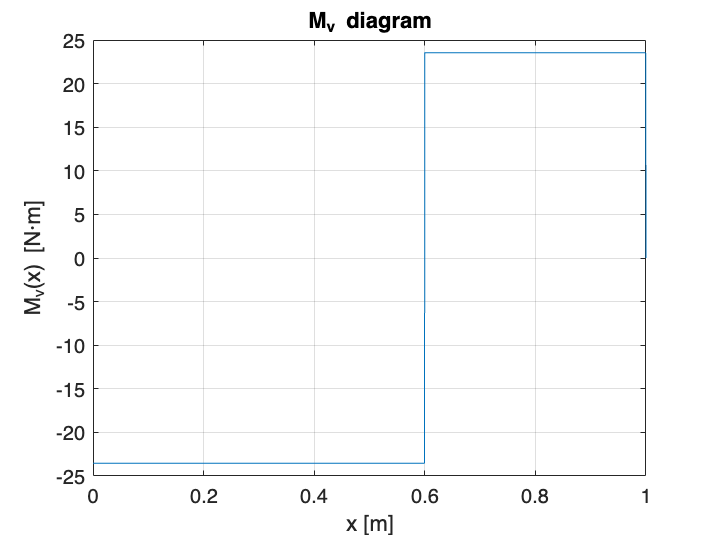

clear; close all; clc;

%%Load tidligere resultater
load('bil_ligevaegt.mat','bil');
load('aksel_ligevaegt.mat','aksel');

F_D = bil.F_D;     % [N]
N_B = bil.N_B;     % [N]

F_K = aksel.F_K;      % [N]
R_1y = aksel.R_1y; R_2y = aksel.R_2y;   % [N]
R_1z = aksel.R_1z; R_2z = aksel.R_2z;   % [N]

%%Geometridefinitioner
b = 1; %m
b_1 = 0.1; %m
b_d = 0.1; %m
r_d = 0.08; %m
d_h = 0.12; %m

T0 = F_K * r_d;              % [N*m] moment ind ved tandhjul
Th = (F_D/2) * (d_h/2);      % [N*m] moment ud ved hvert hjul

%stykvis-definitions-kanter
x_vhjul = 0;
x_b1 = b_1;
x_t = b/2 + b_d;
x_b2 = b - b_1;
x_hhjul = b;

%%Punktlaster i y-planet
lasterY = [x_vhjul, -F_D/2; x_hhjul, -F_D/2;
    x_t, -F_K; x_b1, -R_1y; x_b2, -R_2y];

%%Punklaster i z-planet
lasterZ = [x_vhjul, -N_B/2; x_hhjul, -N_B/2;
    x_b1, -R_1z; x_b2, -R_2z];

%%Momenter
momenter = [x_vhjul, -Th; x_t, +T0; x_hhjul, -Th];

x = linspace(0,b,2001);


%%Torsion
M_v = zeros(size(x));

for i = 1:numel(x)
    x_i = x(i);
    venstreMoment = momenter(momenter(:,1) <= x_i, :);
    M_v(i) = sum(venstreMoment(:,2));
end

figure;
plot(x, M_v);
grid on
xlabel('x [m]');
ylabel('M_v(x) [N·m]');
title('M_v diagram');


%Forskydning og moment i Y-plan (V_y og M_z)
V_y = zeros(size(x));
M_z = zeros(size(x));

for i = 1:numel(x)
    x_i = x(i);
    venstreKraft = lasterY(lasterY(:,1) <= x_i, :); %Udvælg krafterne i laster y der ligger til venstre for x_i
    V_y(i) = sum(venstreKraft(:,2));
    M_z(i) = -sum(venstreKraft(:,2) .* (x_i - venstreKraft(:,1)));
end

%Forskydning og moment i Z-plan (V_z og M_y)
V_z = zeros(size(x));
M_y = zeros(size(x));

for i = 1:numel(x)
    x_i = x(i);
    venstreKraft = lasterZ(lasterZ(:,1) <= x_i, :); %Udvælg krafterne i laster Z der ligger til venstre for x_i
    V_z(i) = sum(venstreKraft(:,2));
    M_y(i) = sum(venstreKraft(:,2) .* (x_i - venstreKraft(:,1)));
end

figure;
plot(x, V_y);
grid on
xlabel('x [m]');
ylabel('V_y(x) [m]');
title('V_y diagram');


figure;
plot(x, V_z);
grid on
xlabel('x [m]');
ylabel('V_z(x) [m]');
title('V_z diagram');


figure;
plot(x, M_y);
grid on
xlabel('x [m]');
ylabel('M_y(x) [N]');
title('M_y diagram');


figure;
plot(x, M_z);
grid on
xlabel('x [m]');
ylabel('M_z(x) [N]');
title('M_z diagram');


%Samlet bøjningsmoment
M_tot = sqrt(M_y.^2 + M_z.^2);   % [N·m]

figure;
plot(x, M_tot);
grid on
xlabel('x [m]');
ylabel('M_{tot}(x) [N·m]');
title('M_{tot} diagram');


%Diameterprofil af aksel
d_aksel = @(xq, D) ( ...
    (xq < x_b1).* (0.6*D) + ...
    (xq >= x_b1 & xq <= x_b2).* (1.0*D) + ...
    (xq > x_b2).* (0.6*D) );

%% Spændinger for en given D
D = 26.6e-3; %22 mm

d = d_aksel(x, D);

sigma_b = (32 .* M_tot) ./ (pi .* d.^3);   % [Pa]
tau_t   = (16 .* M_v)   ./ (pi .* d.^3);   % [Pa]
sigma_vm = sqrt(sigma_b.^2 + 3*tau_t.^2);  % [Pa]

figure; plot(x, tau_t*1e-6); grid on
xlabel('x [m]'); ylabel('\tau [MPa]');
title(sprintf('\\tau(x), D = %.1f mm', D*1e3));


figure; plot(x, sigma_b*1e-6); grid on
xlabel('x [m]'); ylabel('\sigma_b [MPa]');
title(sprintf('\\sigma_b(x), D = %.1f mm', D*1e3));

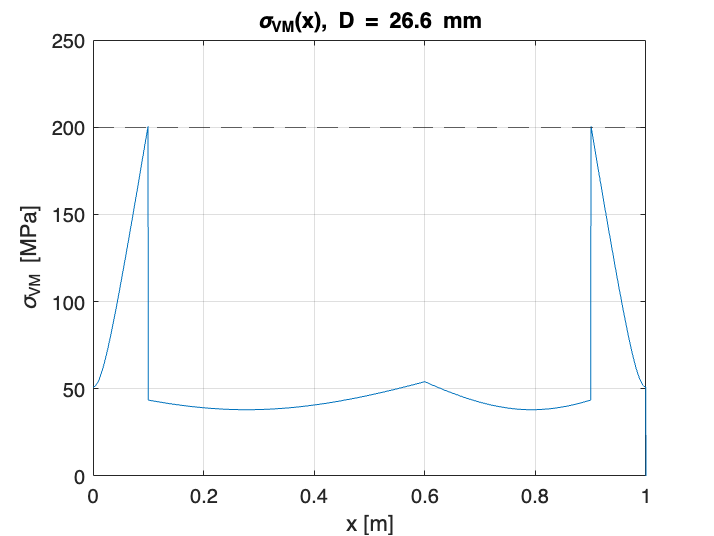


figure; plot(x, sigma_vm*1e-6); grid on
yline(200,'--');  % krav
xlabel('x [m]'); ylabel('\sigma_{VM} [MPa]');
title(sprintf('\\sigma_{VM}(x), D = %.1f mm', D*1e3));


%Visuelt er svaret fundet til 26.6 vha. sigma_VM diagram, dette gøres nu
%komputationelt

%%Find mindste D så max(sigma_vm) <= 200 MPa
sigma_allow = 200e6; % [Pa]
D_grid = linspace(10e-3, 60e-3, 400); %test fra 10–60 mm

vm_max = zeros(size(D_grid)); %vm_max indeholder maksimal von mises spænding for en given D

for k = 1:numel(D_grid)
    Dk = D_grid(k); %D værdi
    dk = d_aksel(x, Dk); %akslens diameter-profil ved D

    sigma_bk = (32 .* M_tot) ./ (pi .* dk.^3); %Bøjningsspænding
    tau_k    = (16 .* M_v)   ./ (pi .* dk.^3); %Forskydningsspænding grundet torsion
    sigma_vmk = sqrt(sigma_bk.^2 + 3*tau_k.^2); %Von mises spænding

    vm_max(k) = max(sigma_vmk); %Gem maksimal von mises spændingg
end

idx = find(vm_max <= sigma_allow, 1, 'first'); %Find første diameter der overholder krav
D_min = D_grid(idx);

fprintf('Mindste diameter der opfylder spændingskrav på 200 MPa: D = %.2f mm\n', D_min*1e3);

Mindste diameter der opfylder spændingskrav på 200 MPa: D = 26.67 mm




%%Spændingskoncentrationer (lokale) ved kritiske skuldre

%Krumningsdiametre
rho1 = 4e-3;   % [m]
rho2 = 4e-3;   % [m]

% Kritiske x-positioner
xCrit = [0.1, 0.6, 0.9];  % [m]
names = ["Venstre skulder (x=0.1)", "Tandhjul (x=0.6)", "Højre skulder (x=0.9)"];

%Find nærmeste indeks i x-grid
idxCrit = arrayfun(@(xc) find(abs(x - xc) == min(abs(x - xc)), 1), xCrit);

% Kt-værdier fra slides
% D/d ved yder-skuldre er 1/0.6 = 1,667, rho/d ved yder-skuldre er 4 mm/
% 0.6*26.6 mm = 0.25 => derfor er K_t,b = 1.35 her og k_t,v =1.2
% Ved tandhjuler er D/d = 2 og rho/d = 0.15 => K_t,b = 1.55 og k_t,v = 1.35
Kt_b = [1.35, 1.55, 1.35];
Kt_v = [1.20, 1.35, 1.20];

% lille "eps" til at sample venstre/højre side af skulderen
epsx = x(2) - x(1);

%Lokal von Mises ved punkterne
sigma_vm_local = zeros(size(xCrit));

for j = 1:numel(xCrit)
    xc = xCrit(j);

    %Moment og torsion tages ved selve sektionen
    ii = idxCrit(j);
    M_here = M_tot(ii);
    T_here = M_v(ii);

    %Diameter lige til venstre og højre for skulderen
    dL = d_aksel(xc - epsx, D);
    dR = d_aksel(xc + epsx, D);

    %Kritisk diameter = den lille
    d_small = min(dL, dR);

    %Nominale spændinger på lille diameter
    sigma_b_nom = (32 * M_here) / (pi * d_small^3);  %[Pa]
    tau_t_nom   = (16 * T_here) / (pi * d_small^3);  %[Pa]

    %Lokale spændinger med Kt'er
    sigma_b_loc = Kt_b(j) * sigma_b_nom;
    tau_t_loc   = Kt_v(j) * tau_t_nom;

    sigma_vm_local(j) = sqrt(sigma_b_loc^2 + 3*tau_t_loc^2);
end

fprintf('\n--- Lokale spændinger ved skuldre (med lille diameter) ---\n');


--- Lokale spændinger ved skuldre (med lille diameter) ---


for j = 1:numel(xCrit)
    fprintf('%s: sigma_vm_local = %.1f MPa\n', names(j), sigma_vm_local(j)*1e-6);
end

Venstre skulder (x=0.1): sigma_vm_local = 270.3 MPa
Tandhjul (x=0.6): sigma_vm_local = 83.4 MPa
Højre skulder (x=0.9): sigma_vm_local = 270.3 MPa



%Check mod samme tilladelige spænding som før (400/2 = 200 MPa)
sigma_allow = 200e6; % [Pa]
if any(sigma_vm_local > sigma_allow)
    fprintf('=> FAIL: Mindst ét kritisk punkt overskrider %.0f MPa\n', sigma_allow*1e-6);
else
    fprintf('=> OK: Alle kritiske punkter under %.0f MPa\n', sigma_allow*1e-6);
end

=> FAIL: Mindst ét kritisk punkt overskrider 200 MPa


Altså overskirdes den kritiske spænding allerede nu ved yderskuldrene. Vi skal dog også tage højde for fatigue.

sigma_ub = 300e6;     % [Pa] fattighedsgrænse for bøjning i lab, R=-1
Rm       = 640e6;     % [Pa] Brudstyrke
rho      = 4e-3;      % [m] rundingsradius
lambda   = 1.0;
Kd       = 1.0;

%q aflæses til 0.84 for Rm=640 MPa og rho=4 mm
q = 0.84

q = 0.8400

%overfladeruhed -> 1/Kr = 0.81
Kr = 1/0.81;

%Kritiske steder for fatigue
xFat = [0.1, 0.9];
names = ["Venstre skulder(0.1)", "Højre skulder (0.9)"];

%Kt i bøjning ved hjulskuldre (fra tidligere)
Kt_b = 1.35;

%Notch-reduktion i fatigue (Kf) ud fra Kt og q:
Kf = 1 + q*(Kt_b - 1);

%Reduceret fatigue limit:
sigma_ub_red = (lambda/(Kd*Kf*Kr)) * sigma_ub;  % [Pa]

fprintf('\n--- Fatigue limit (bending, R=-1) ---\n');


--- Fatigue limit (bending, R=-1) ---


fprintf('Kf = %.3f, Kr = %.3f  => sigma_ub_red = %.1f MPa\n', ...
    Kf, Kr, sigma_ub_red*1e-6);

Kf = 1.294, Kr = 1.235  => sigma_ub_red = 187.8 MPa



sigma_a = 200e6;  % [Pa]
sigma_m = 0;      % [Pa] (R=-1)

%Safety factor mod fatigue:
n_fat = sigma_ub_red / sigma_a;

for i = 1:numel(xFat)
    fprintf('%s: n_fat = %.2f\n', names(i), n_fat);
end

Venstre skulder(0.1): n_fat = 0.94
Højre skulder (0.9): n_fat = 0.94



if n_fat < 1
    fprintf('=> FAIL: udmattelse forventes ved x=0.1 eller 0.9 (n=%.2f)\n', n_fat);
else
    fprintf('=> OK: sikker mod udmattelse (n=%.2f)\n', n_fat);
end

=> FAIL: udmattelse forventes ved x=0.1 eller 0.9 (n=0.94)


Altså forventes udmattelse også her.

Den mindste diameter der overholder kravene findes nu.

ok_static = false(size(D_grid));
ok_fatigue = false(size(D_grid));

Kt_b = [1.35, 1.55, 1.35];
Kt_v = [1.20, 1.35, 1.20];

%Indeks til fatigue-punkter (yderskuldre)
idxFat = arrayfun(@(xc) find(abs(x-xc)==min(abs(x-xc)),1), xFat);

for k = 1:numel(D_grid)
    Dk = D_grid(k);

    %%statisk lokalt check ved xCrit (VM med Kt) på lille diameter
    sigma_vm_local_k = zeros(size(xCrit));

    for j = 1:numel(xCrit)
        xc = xCrit(j);
        ii = idxCrit(j);

        M_here = M_tot(ii);
        T_here = M_v(ii);

        dL = d_aksel(xc - epsx, Dk);
        dR = d_aksel(xc + epsx, Dk);
        d_small = min(dL, dR);

        sigma_b_nom = (32*M_here)/(pi*d_small^3);
        tau_t_nom   = (16*T_here)/(pi*d_small^3);

        sigma_b_loc = Kt_b(j)*sigma_b_nom;
        tau_t_loc   = Kt_v(j)*tau_t_nom;

        sigma_vm_local_k(j) = sqrt(sigma_b_loc^2 + 3*tau_t_loc^2);
    end

    ok_static(k) = max(sigma_vm_local_k) <= sigma_allow;

    %%Fatigue check
    sigma_a_k = zeros(size(xFat));

    for j = 1:numel(xFat)
        xc = xFat(j);
        ii = idxFat(j);

        M_here = M_tot(ii);

        dL = d_aksel(xc - epsx, Dk);
        dR = d_aksel(xc + epsx, Dk);
        d_small = min(dL, dR);

        sigma_a_k(j) = (32*M_here)/(pi*d_small^3);
    end

    ok_fatigue(k) = max(sigma_a_k) <= sigma_ub_red;
end

ok_both = ok_static & ok_fatigue;

idx = find(ok_both, 1, 'first');
if isempty(idx)
    fprintf('\n=> Ingen D i D_grid opfylder både lokal statik og fatigue.\n');
else
    D_min_both = D_grid(idx);
    fprintf('\n=> Mindste D der opfylder (lokal statik + fatigue): D = %.2f mm\n', D_min_both*1e3);
end


=> Mindste D der opfylder (lokal statik + fatigue): D = 29.42 mm
